% PARAMETERS
x_init_nf = [0, 9*10^-13, 0, 0, 0, 10^-13, 0, 0, 10^-12, 0, 10^-13, 0, 0.31, 99.4, 0.29, 100, 0, 100, 0, 96, 4];
x_init  = [0, 9*10^-13, 0, 0, 0, 10^-13, 0, 0, 10^-12, 0, 10^-13, 0, 0.31, 99.4, 0.29, 100, 0, 100, 0, 96, 4, 0];
tspan   = linspace(0,60,31);
tau     = 1.5;
options = odeset('RelTol',1e-12,'AbsTol',[1e-12]);

% NO MODIFICATIONS; NONLINEAR INSULIN
[t_nf, x_nf] = ode45(@InsulinModel,tspan,x_init_nf,options);

% FEEDBACK, CONSTANT INSULIN
f_const_insulin = dde23(@InsulinModelFeedback,tau,x_init,tspan,options,[1,0]);
t_f_const_insulin = f_const_insulin.x; x_f_const_insulin = transpose(f_const_insulin.y);

% FEEDBACK, NONLINEAR INSULIN
f_nl_insulin = dde23(@InsulinModelFeedback,tau,x_init,tspan,options,[1,0]);
t_f_nl_insulin = f_nl_insulin.x; x_f_nl_insulin = transpose(f_nl_insulin.y);

% MODIFY Kdeg
% Kdeg: 0.1x
sol_kdeg_01 = dde23(@InsulinModelFeedback,tau,x_init,tspan,options,[1, 0.1]);
t_kdeg_01 = sol_kdeg_01.x; x_kdeg_01 = transpose(sol_kdeg_01.y);

% Kdeg: 1x
sol_kdeg_1 = dde23(@InsulinModelFeedback,tau,x_init,tspan,options,[1, 1]);
t_kdeg_1 = sol_kdeg_1.x; x_kdeg_1 = transpose(sol_kdeg_1.y);

% Kdeg: 10x
sol_kdeg_10 = dde23(@InsulinModelFeedback,tau,x_init,tspan,options,[1, 10]);
t_kdeg_10 = sol_kdeg_10.x; x_kdeg_10 = transpose(sol_kdeg_10.y);

% Kdeg: 50x
sol_kdeg_50 = dde23(@InsulinModelFeedback,tau,x_init,tspan,options,[1, 50]);
t_kdeg_50 = sol_kdeg_50.x; x_kdeg_50 = transpose(sol_kdeg_50.y);

% Kdeg: 100x
sol_kdeg_100 = dde23(@InsulinModelFeedback,tau,x_init,tspan,options,[1, 100]);
t_kdeg_100 = sol_kdeg_100.x; x_kdeg_100 = transpose(sol_kdeg_100.y);

% Kdeg: 500x
sol_kdeg_500 = dde23(@InsulinModelFeedback,tau,x_init,tspan,options,[1, 500]);
t_kdeg_500 = sol_kdeg_500.x; x_kdeg_500 = transpose(sol_kdeg_500.y);

% MODIFY K7p
% Kdeg: 0.1x
sol_k7p_01 = dde23(@InsulinModelFeedback,tau,x_init,tspan,options,[0.1, 1]);
t_k7p_01 = sol_k7p_01.x; x_k7p_01 = transpose(sol_k7p_01.y);

% Kdeg: 1x
sol_k7p_1 = dde23(@InsulinModelFeedback,tau,x_init,tspan,options,[1, 1]);
t_k7p_1 = sol_k7p_1.x; x_k7p_1 = transpose(sol_k7p_1.y);

% Kdeg: 10x
sol_k7p_10 = dde23(@InsulinModelFeedback,tau,x_init,tspan,options,[10, 1]);
t_k7p_10 = sol_k7p_10.x; x_k7p_10 = transpose(sol_k7p_10.y);

% Kdeg: 50x
sol_k7p_50 = dde23(@InsulinModelFeedback,tau,x_init,tspan,options,[50, 1]);
t_k7p_50 = sol_k7p_50.x; x_k7p_50 = transpose(sol_k7p_50.y);

% Kdeg: 100x
sol_k7p_100 = dde23(@InsulinModelFeedback,tau,x_init,tspan,options,[100, 1]);
t_k7p_100 = sol_k7p_100.x; x_k7p_100 = transpose(sol_k7p_100.y);

% Kdeg: 500x
sol_k7p_500 = dde23(@InsulinModelFeedback,tau,x_init,tspan,options,[500, 1]);
t_k7p_500 = sol_k7p_500.x; x_k7p_500 = transpose(sol_k7p_500.y);

% MODIFY BOTH K7p and Kdeg
% Kdeg: 0.1x
sol_k_01 = dde23(@InsulinModelFeedback,tau,x_init,tspan,options,[0.1, 0.1]);
t_k_01 = sol_k_01.x; x_k_01 = transpose(sol_k_01.y);

% Kdeg: 1x
sol_k_1 = dde23(@InsulinModelFeedback,tau,x_init,tspan,options,[1, 1]);
t_k_1 = sol_k_1.x; x_k_1 = transpose(sol_k_1.y);

% Kdeg: 10x
sol_k_10 = dde23(@InsulinModelFeedback,tau,x_init,tspan,options,[10, 10]);
t_k_10 = sol_k_10.x; x_k_10 = transpose(sol_k_10.y);

% Kdeg: 50x
sol_k_50 = dde23(@InsulinModelFeedback,tau,x_init,tspan,options,[50, 50]);
t_k_50 = sol_k_50.x; x_k_50 = transpose(sol_k_50.y);

% Kdeg: 100x
sol_k_100 = dde23(@InsulinModelFeedback,tau,x_init,tspan,options,[100, 100]);
t_k_100 = sol_k_100.x; x_k_100 = transpose(sol_k_100.y);

% Kdeg: 500x
sol_k_500 = dde23(@InsulinModelFeedback,tau,x_init,tspan,options,[500, 500]);
t_k_500 = sol_k_500.x; x_k_500 = transpose(sol_k_500.y);

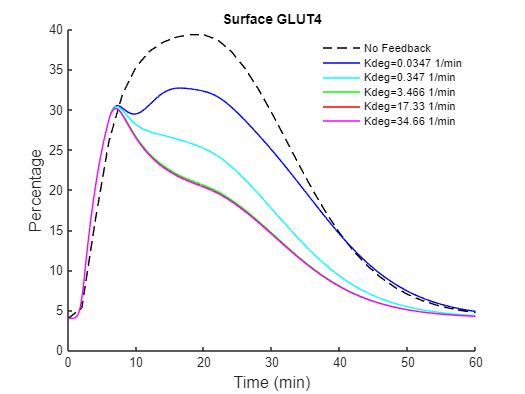

% PLOT RESULTS FOR Kdeg Changes
figure();
hold on
plot(t_nf,  x_nf(:,21), '--k')
plot(t_kdeg_01,  x_kdeg_01(:,21), 'blue')
plot(t_kdeg_1,  x_kdeg_1(:,21), 'cyan')
plot(t_kdeg_10,  x_kdeg_10(:,21), 'green')
plot(t_kdeg_50,  x_kdeg_50(:,21), 'red')
plot(t_kdeg_100,  x_kdeg_100(:,21), 'magenta')
hold off
ylim([0,40])
set(gca, 'box', 'off')

L = legend("No Feedback","Kdeg=0.0347 1/min","Kdeg=0.347 1/min","Kdeg=3.466 1/min","Kdeg=17.33 1/min","Kdeg=34.66 1/min", 'FontSize', 9, "Location", "northeast");
legend boxoff 

title("Surface GLUT4")
xlabel("Time (min)", 'FontSize', 13); 
ylabel("Percentage", 'FontSize', 13)

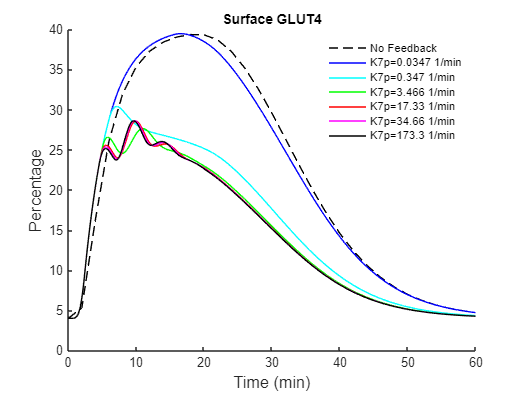

% PLOT RESULTS FOR K7p Changes
figure();
hold on
plot(t_nf,  x_nf(:,21), '--k')
plot(t_k7p_01,  x_k7p_01(:,21), 'blue')
plot(t_k7p_1,  x_k7p_1(:,21), 'cyan')
plot(t_k7p_10,  x_k7p_10(:,21), 'green')
plot(t_k7p_50,  x_k7p_50(:,21), 'red')
plot(t_k7p_100,  x_k7p_100(:,21), 'magenta')
plot(t_k7p_500,  x_k7p_500(:,21), 'black')
hold off
ylim([0,40])
set(gca, 'box', 'off')

L = legend("No Feedback","K7p=0.0347 1/min","K7p=0.347 1/min","K7p=3.466 1/min","K7p=17.33 1/min","K7p=34.66 1/min","K7p=173.3 1/min", 'FontSize', 9, "Location", "northeast");
legend boxoff 

title("Surface GLUT4")
xlabel("Time (min)", 'FontSize', 13); 
ylabel("Percentage", 'FontSize', 13)

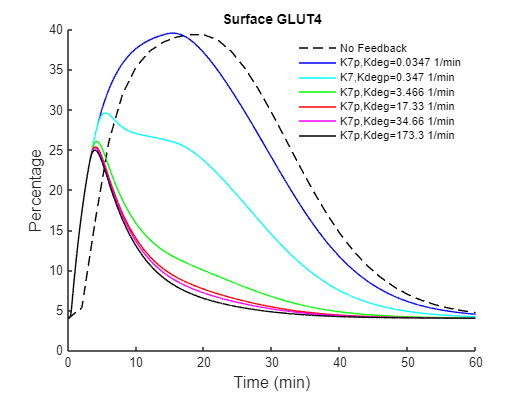

% PLOT RESULTS FOR BOTH Changes
figure();
hold on
plot(t_nf,  x_nf(:,21), '--k')
plot(t_k_01,  x_k_01(:,21), 'blue')
plot(t_k_1,  x_k_1(:,21), 'cyan')
plot(t_k_10,  x_k_10(:,21), 'green')
plot(t_k_50,  x_k_50(:,21), 'red')
plot(t_k_100,  x_k_100(:,21), 'magenta')
plot(t_k_500,  x_k_500(:,21), 'black')
hold off
ylim([0,40])
set(gca, 'box', 'off')

L = legend("No Feedback","K7p,Kdeg=0.0347 1/min","K7,Kdegp=0.347 1/min","K7p,Kdeg=3.466 1/min","K7p,Kdeg=17.33 1/min","K7p,Kdeg=34.66 1/min","K7p,Kdeg=173.3 1/min", 'FontSize', 9, "Location", "northeast");
legend boxoff 

title("Surface GLUT4")
xlabel("Time (min)", 'FontSize', 13); 
ylabel("Percentage", 'FontSize', 13)

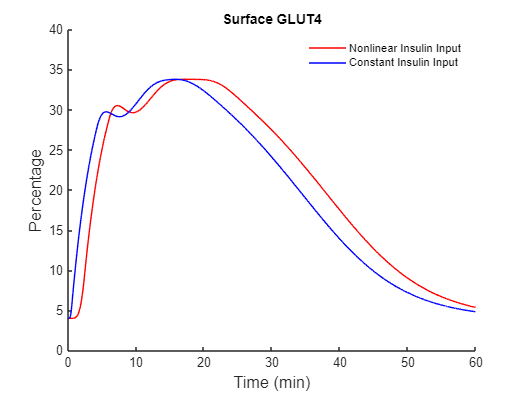

% PLOT GLUT4 FOR CONSTANT VS NONLINEAR INSULIN
figure();
hold on
plot(t_f_nl_insulin,  x_f_nl_insulin(:,21), 'red')
plot(t_f_const_insulin,  x_f_const_insulin(:,21), 'blue')
hold off
ylim([0,40])
set(gca, 'box', 'off')

L = legend("Nonlinear Insulin Input","Constant Insulin Input", 'FontSize', 9, "Location", "northeast");
legend boxoff 

title("Surface GLUT4")
xlabel("Time (min)", 'FontSize', 13); 
ylabel("Percentage", 'FontSize', 13)

function dxdt = InsulinModelFeedback(t,x,z,scaler)

% TIME DELAY
xlag19 = z(19);

% PARAMETERS
IRp     = 8.97 * 10^-13;
SHIP    = 1;
PTEN    = 1;
APeq    = 100/11;
effect  = min((0.2.*x(17) + 0.8.*x(19)) ./ APeq, 1);
Vmax    = 20;
Kd      = 12;
n       = 4;
PKC     = (Vmax.*xlag19.^n)./(Kd^n + xlag19.^n);
if x(17) <= 400/11
    PTP = 1.0.*(1-0.25.*(x(17)./(APeq))); 
else
    PTP = 0;
end

% MODIFICATIONS
k7_     = log(2) / 2 .* scaler(1);
kdeg    = log(2) / 2 .* scaler(2);

if t < 15
    x(1,:) = 10^-7; %- 0.5 * 10^-7 * cos(0.3 * t) + 0.5 * 10^-7;
else 
    x(1,:) = 0;
end

% RATE CONSTANTS
k1      = 6 * 10^7;
k_1     = 0.20;
k2      = k1;
k_2     = 100 * k_1;
k3      = 2500;
k_3     = k_1;
k_4     = 0.003;
k4      = k_4/9;  
k4_     = 2.1 * 10^-3; 
k_4_    = 2.1 * 10^-4;
k_5     = 1.67 * 10^-18;
k5      = get_k5(x(6), x(7), x(8), k_5);
k6      = 0.461;     
k7      = 4.16;
k_7     = (2.5/7.45) * k7;
k_7_    = k7_*((2.5/7.45)*(3.7*10^-13))/((6.27*10^-13)-((2.5/7.45)*(3.7*10^-13)));
k_8     = 10;
k8      = k_8 * (5/70.775) * 10^12;  
PI3K    = k8 * (3.70*10^-13) * (10^-13) / (k8 * (3.70*10^-13) + k_8);
k9_sim  = 1.39;
k_9     = (94/3.1) * k9_sim;
k9_bas  = (0.31/99.4) * k_9;
k9      = (k9_sim - k9_bas) .* (x(12) ./ PI3K) + k9_bas;  
k_10    = 2.77;
k10     = (3.1/2.9) * k_10;  
k_11    = 10 * log(2);
k11     = 0.1 .* k_11 .* (x(13) - 0.31) ./ (3.10-0.31); 
k_12    = 10 * log(2);
k12     = 0.1 .* k_12 .* (x(13) - 0.31) ./ (3.10-0.31); 
k_13    = 0.167;
k13     = (4/96) * k_13;   
k13_    = (40/60 - 4/96) .* k_13 .* effect;
k_14    = 0.001155;
k14     = 96 * k_14; 

% DIFFERENTIAL EQUATIONS
dxdt = [];
dxdt(2,:)  = k_1.*x(3) + k_3.*PTP.*x(5) - k1.*x(1).*x(2) + k_4.*x(6) - k4.*x(2);
dxdt(3,:)  = k1.*x(1).*x(2) - k_1.*x(3) - k3.*x(3);
dxdt(4,:)  = k2.*x(1).*x(5) - k_2.*x(4) + k_4_.*x(7) - k4_.*x(4);
dxdt(5,:)  = k3.*x(3) + k_2.*x(4) - k2.*x(1).*x(5) - k_3.*PTP.*x(5) + k_4_.*x(8) - k4_.*x(5);
dxdt(6,:)  = k5 - k_5.*x(6) + k6.*PTP.*(x(7) + x(8)) + k4.*x(2) - k_4*x(6);
dxdt(7,:)  = k4_.*x(4) - k_4_.*x(7) - k6.*PTP.*x(7);
dxdt(8,:)  = k4_.*x(5) - k_4_.*x(8) - k6.*PTP.*x(8);
dxdt(9,:)  = k_7.*PTP.*x(10) - k7.*x(9).*(x(4) + x(5))./IRp + k_7_.*x(22) - k7_.*PKC.*x(9);
dxdt(10,:) = k7.*x(9).*(x(4) + x(5))./IRp + k_8.*x(12) - (k_7.*PTP + k8.*x(11)).*x(10);
dxdt(11,:) = k_8.*x(12) - k8.*x(10).*x(11);
dxdt(12,:) = k8.*x(10).*x(11) - k_8.*x(12);
dxdt(13,:) = k9.*x(14) + k10.*x(15) - (k_9.*PTEN + k_10.*SHIP).*x(13);
dxdt(14,:) = k_9.*PTEN.*x(13) - k9.*x(14);
dxdt(15,:) = k_10.*SHIP.*x(13) - k10.*x(15);
dxdt(16,:) = k_11.*x(17) - k11.*x(16);
dxdt(17,:) = k11.*x(16) - k_11.*x(17);
dxdt(18,:) = k_12.*x(19) - k12.*x(18);
dxdt(19,:) = k12.*x(18) - k_12.*x(19);
dxdt(20,:) = k_13.*x(21) - (k13 + k13_).*x(20) + k14 - k_14.*x(20);
dxdt(21,:) = (k13 + k13_).*x(20) - k_13.*x(21);
dxdt(22,:) = k7_.*PKC.*x(9) - k_7_.*x(22) - kdeg.*x(22);

end

function dxdt = InsulinModel(t,x)

% PARAMETERS
IRp  = 8.97 * 10^-13;
SHIP = 1;
PTEN = 1;
PTP  = 1; 
APeq = 100/11;
PI3K = 5 * 10^-15;
effect = (0.2.*x(17) + 0.8.*x(19)) ./ APeq;

% RATE CONSTANTS
k1      = 6 * 10^7;
k_1     = 0.20;
k2      = k1;
k_2     = 100 * k_1;
k3      = 2500;
k_3     = k_1;
k_4     = 0.003;
k4      = k_4/9;  
k4_     = 2.1 * 10^-3; 
k_4_    = 2.1 * 10^-4;
k_5     = 1.67 * 10^-18;
k5      = get_k5(x(6), x(7), x(8), k_5);
k6      = 0.461;     
k7      = 4.16;
k_7     = (2.5/7.45) * k7;
k_8     = 10;
k8      = k_8 * (5/70.775) * 10^12;    
k9_sim  = 1.39;
k_9     = (94/3.1) * k9_sim;
k9_bas  = (0.31/99.4) * k_9;
k9      = (k9_sim - k9_bas) .* (x(12) ./ PI3K) + k9_bas;  
k_10    = 2.77;
k10     = (3.1/2.9) * k_10;  
k_11    = 10 * log(2);
k11     = 0.1 .* k_11 .* (x(13) - 0.31) ./ (3.10-0.31); 
k_12    = 10 * log(2);
k12     = 0.1 .* k_12 .* (x(13) - 0.31) ./ (3.10-0.31); 
k_13    = 0.167;
k13     = (4/96) * k_13;   
k13_    = (40/60 - 4/96) .* k_13 .* effect;
k_14    = 0.001155;
k14     = 96 * k_14; 

% INSULIN INPUT
if t < 21
    x(1,:) = - 0.5 * 10^-7 * cos(0.3 * t) + 0.5 * 10^-7;
else 
    x(1,:) = 0;
end

% DIFFERENTIAL EQUATIONS
dxdt = [];
dxdt(1,:)  = 0;
dxdt(2,:)  = k_1.*x(3) + k_3.*PTP.*x(5) - k1.*x(1).*x(2) + k_4.*x(6) - k4.*x(2);
dxdt(3,:)  = k1.*x(1).*x(2) - k_1.*x(3) - k3.*x(3);
dxdt(4,:)  = k2.*x(1).*x(5) - k_2.*x(4) + k_4_.*x(7) - k4_.*x(4);
dxdt(5,:)  = k3.*x(3) + k_2.*x(4) - k2.*x(1).*x(5) - k_3.*PTP.*x(5) + k_4_.*x(8) - k4_.*x(5);
dxdt(6,:)  = k5 - k_5.*x(6) + k6.*PTP.*(x(7) + x(8)) + k4.*x(2) - k_4*x(6);
dxdt(7,:)  = k4_.*x(4) - k_4_.*x(7) - k6.*PTP.*x(7);
dxdt(8,:)  = k4_.*x(5) - k_4_.*x(8) - k6.*PTP.*x(8);
dxdt(9,:)  = k_7.*PTP.*x(10) - k7.*x(9).*(x(4) + x(5))./IRp;
dxdt(10,:) = k7.*x(9).*(x(4) + x(5))./IRp + k_8.*x(12) - (k_7.*PTP + k8.*x(11)).*x(10);
dxdt(11,:) = k_8.*x(12) - k8.*x(10).*x(11);
dxdt(12,:) = k8.*x(10).*x(11) - k_8.*x(12);
dxdt(13,:) = k9.*x(14) + k10.*x(15) - (k_9.*PTEN + k_10.*SHIP).*x(13);
dxdt(14,:) = k_9.*PTEN.*x(13) - k9.*x(14);
dxdt(15,:) = k_10.*SHIP.*x(13) - k10.*x(15);
dxdt(16,:) = k_11.*x(17) - k11.*x(16);
dxdt(17,:) = k11.*x(16) - k_11.*x(17);
dxdt(18,:) = k_12.*x(19) - k12.*x(18);
dxdt(19,:) = k12.*x(18) - k_12.*x(19);
dxdt(20,:) = k_13.*x(21) - (k13 + k13_).*x(20) + k14 - k_14.*x(20);
dxdt(21,:) = (k13 + k13_).*x(20) - k_13.*x(21);

end

% RATE CONSTANT FUNCTION
function k5 = get_k5(a,b,c,k_5)
    if (a + b + c) > 10^-13
        k5  = 10 * k_5;
    else 
        k5  = 60 * k_5;
    end
end